%different parametes study for go-kart
syms fr mue Y C e l x v
g=9.81; %m/s^2
m=200; %kg
l2=0.55;     %m
l1=0.92-0.55;    %m
l=l1+l2;     %m
mue=0.8;     %for rubber with dry asphelt
fr=0.0125;
W=m*g;  %N
kf=0.1:0.1:1;
kr=1-kf;
h=0.5;
theta=0;

in the previous steps we just plogged in the different parameteres and their values

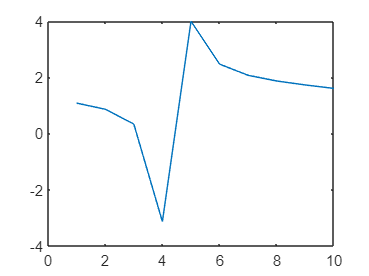

%deceleration calculation
for i=1:10
    df(i)=(mue*l2+kf(i)*fr)/(kf(i)-mue*h/l);
    dr(i)=(mue*l1+kr(i)*fr)/(kr(i)+mue*h/l);
end
%braking forces calculation
for i=1:10
    Fbf(i)=mue*kf(i)*W*(df(i)-fr);
    Fbr(i)=mue*(1-kf(i))*W*(dr(i)-fr);
end
%Reaction forces calculation
for i=1:10
    Wf(i)=1/l*(W*l2+h*(Fbf(i)+fr*W));
    Wr(i)=1/l*(W*l2-h*(Fbr(i)+fr*W));
end
for i=1:10
    ratioW(i)=Wf(i)/Wr(i);
end
plot(ratioW)

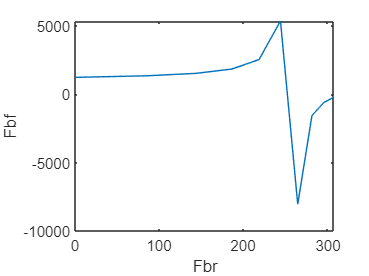

%plotting data
plot(Fbr,Fbf)
xlabel("Fbr"),ylabel("Fbf")

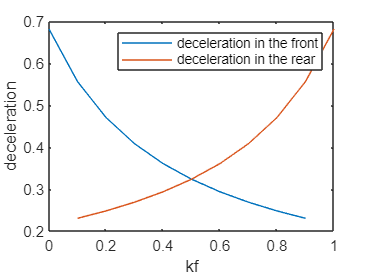

plot(kr,dr)
xlabel("kr"),ylabel("df")
hold on
plot(kf,dr)
xlabel("kf"),ylabel("deceleration")
%Approximating data
%F=0.2*exp(0.5*log(x^-1))
%fplot(F)
legend("deceleration in the front","deceleration in the rear")
hold off

%fplot(-F)
%Maximum braking distance:
C=l*1*1.225/2;
Y=1.4;
v=1:2:50;
%Maximum braking distance calc
for i=1:25
    s(i)=Y*W/(2*g*C)*log(1+(C*v(i)^2)/(mue*W+fr*cos(theta)+W*sin(theta)));
end
%Approximating data
%fplot(3.1*exp(0.12*x))
%hold off
plot(v*3.6,s)
hold on 

Now let us poltting the data

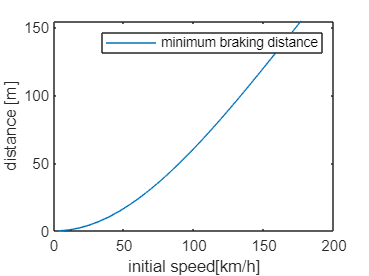

xlabel("initial speed[km/h]")
ylabel("distance [m]")
legend("minimum braking distance")
%minimum braking time
for i=1:25
    t(i)=v(i)/(fr+mue);
end
%distance based on newton 2nd law
for i=1:25
    s2(i)=v(i)*t(i)-1/2*(fr+mue)*t(i)^2;
end
hold off

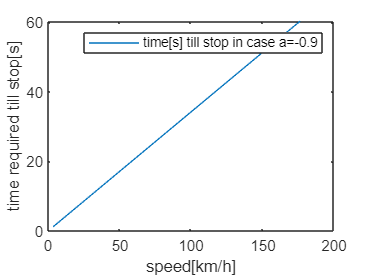

plot(v*3.6,t)
xlabel("speed[km/h]")
ylabel("time required till stop[s]")
legend("time[s] till stop in case a=-0.9")

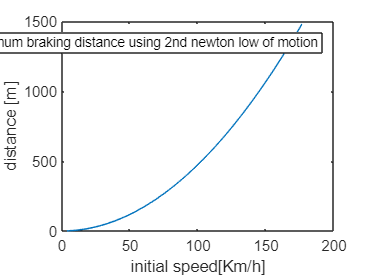

%plotting data
plot(v*3.6,s2)
xlabel("initial speed[Km/h]")
ylabel("distance [m]")
legend("minimum braking distance using 2nd newton low of motion")

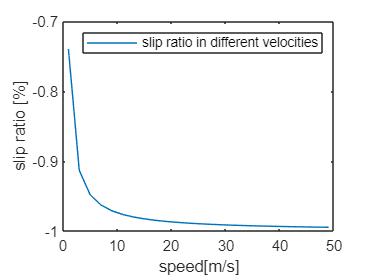

%discussing the slip in perecent 
w=1; %1/s
R=0.26;  % m
for i=1:25
    slip(i)=-(v(i)-w*R)/v(i);
end
plot(v,slip)
xlabel("speed[m/s]")
ylabel("slip ratio [%]")
legend("slip ratio in different velocities ")

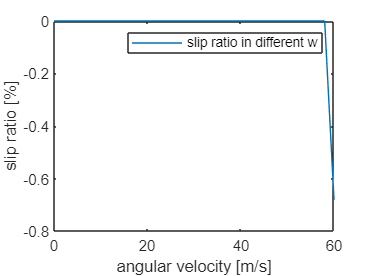

%slip ratio in different w
w=0:2:60; %1/s
for i=1:31
    slip2(31)=-(v(25)-w(i)*R)/v(25);
end
plot(w,slip2)
xlabel("angular velocity [m/s]")
ylabel("slip ratio [%]")
legend("slip ratio in different w ")

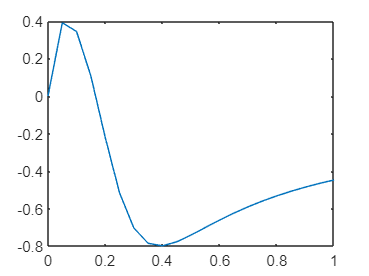

slip3=0:0.05:1;
for i=1:21
    F(i)=mue*sin(1.9*atan(10*slip3(i)-0.97*(10*slip3(i)*atan(10*slip3(i)))));
end
plot(slip3,F)